Part 1.

 AWGN 

**Additive white Gaussian noise** (**AWGN**) is a basic noise model used in [Information theory](https://en.wikipedia.org/wiki/Information_theory) to mimic the effect of many random processes that occur in nature. The modifiers denote specific characteristics.

- ***Additive*** because it is added to any noise that might be intrinsic to the information system.

- ***White*** refers to the idea that it has uniform to power across the frequency band for the information system. It is an analogy to the color white which has uniform emissions at all frequencies in the [visible spectrum](https://en.wikipedia.org/wiki/Visible_spectrum).

- ***Gaussian*** because it has a [normal distribution](https://en.wikipedia.org/wiki/Normal_distribution) in the time domain with an average time domain value of zero.

**What is a Histogram:**

A **histogram** is an accurate representation of the [distribution](https://en.wikipedia.org/wiki/Frequency_distribution) of numerical data. It is an estimate of the [probability distribution](https://en.wikipedia.org/wiki/Probability_distribution) of a [continuous variable](https://en.wikipedia.org/wiki/Continuous_variable) and was first introduced by Karl Pearson.

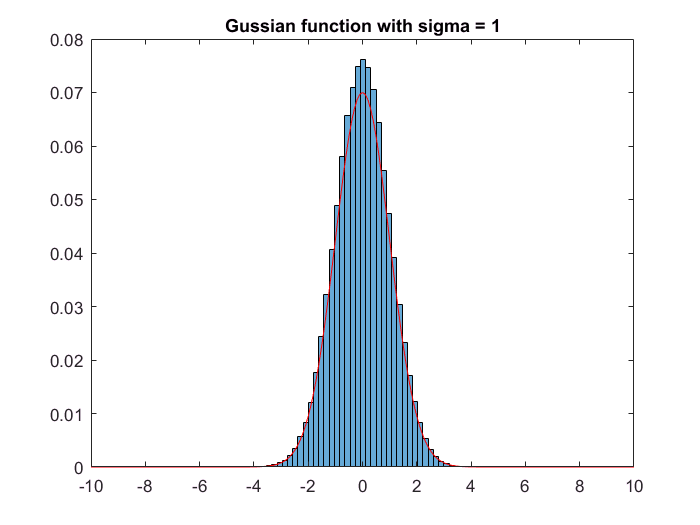

N = 99999;
n_bins=45;
Z_array = zeros(1,N);
rng('shuffle');
Data_1 = normrnd(0,1,size(Z_array));
histogram(Data_1,n_bins,'Normalization','probability');
hold on
x = -10:0.1:10;
Gussian_1 = 0.07.*gaussmf(x,[1 0]);
plot(x,Gussian_1,'r')
title('Gussian function with sigma = 1')
hold off

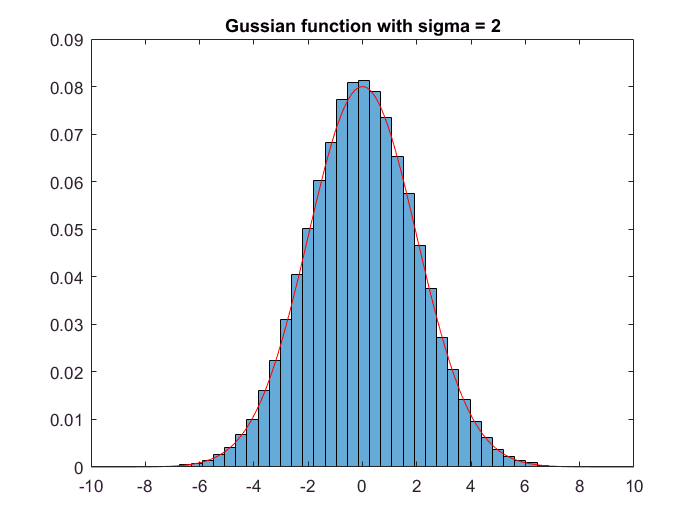

N = 99999;
n_bins=45;
Z_array = zeros(1,N);
rng('shuffle');
Data_2 = normrnd(0,2,size(Z_array));
histogram(Data_2,n_bins,'Normalization','probability');
hold on
x = -10:0.1:10;
Gussian_2 = 0.08 .* gaussmf(x,[2 0]);
plot(x,Gussian_2,'r')
title('Gussian function with sigma = 2')
hold off

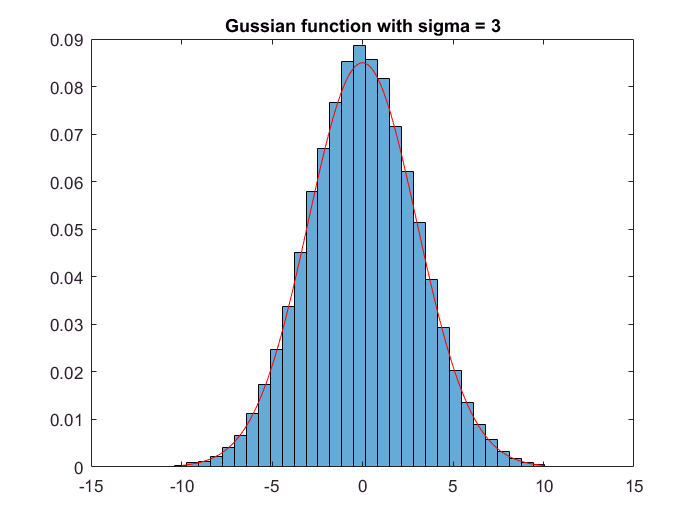

N = 99999;
n_bins=45;
Z_array = zeros(1,N);
rng('shuffle');
Data_3 = normrnd(0,3,size(Z_array));
histogram(Data_3,n_bins,'Normalization','probability');
hold on
x = -10:0.1:10;
Gussian_3 = 0.085 .* gaussmf(x,[3 0]);
plot(x,Gussian_3,'r')
title('Gussian function with sigma = 3')
hold off

Part 2.

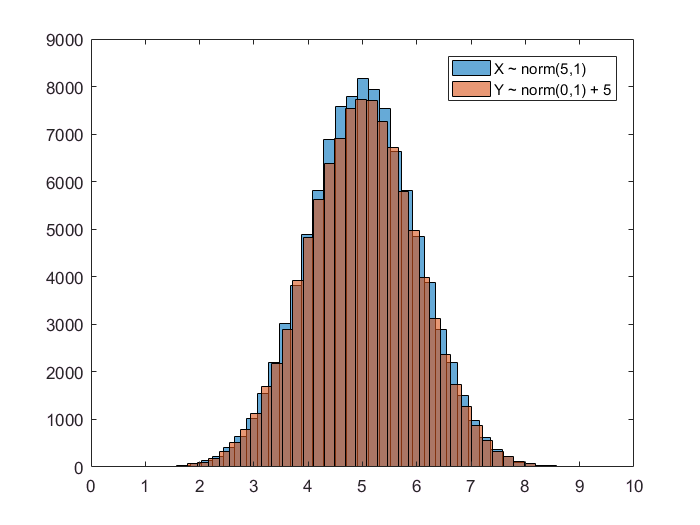

N = 99999;
n_bins=45;
Z_array = zeros(1,N);
rng('shuffle');
Data_p25 = normrnd(5,1,size(Z_array));
histogram(Data_p25,n_bins);
hold on
Data_p20 = normrnd(0,1,size(Z_array));
histogram(Data_p20 + 5 ,n_bins);
legend('X ~ norm(5,1)','Y ~ norm(0,1) + 5')
hold off

X ~ norm(5,1)

Y ~ norm(0,1) + 5

Z ~ norm (0,1)

E[X] = 5

E[Y] = E[Z + 5] = E[Z] + 5 = 0 + 5 = 5 

Part 3.

because the probability of +A is equal to the pobability of -A so there will be two gaussian distribution with variance 0.5.

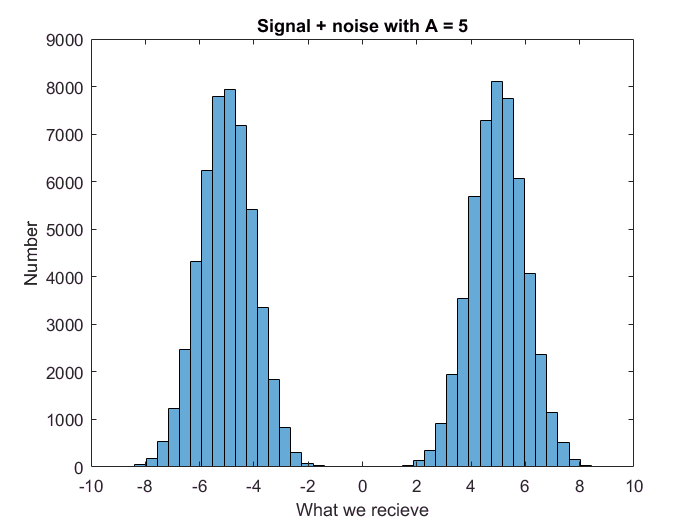

N = 99999;
n_bins=45;
Z_array = zeros(1,N);
rng('shuffle');
Noise_3 = normrnd(0,1,size(Z_array));
Signal_3 = 5.*(2.* randi([0 ,1],[1,N])- 1);
R_3 = Signal_3 + Noise_3;
histogram(R_3,n_bins);
xlabel ('What we recieve');
ylabel ('Number');
title ('Signal + noise with A = 5')

Part 4.

of course the level of our decision will change because now the probability of bieng -A is more than +A so as we can see our probability distribution is focused around -1 so our new ground level will be (-1)*0.7 + (+1)*0.3 = -0.4

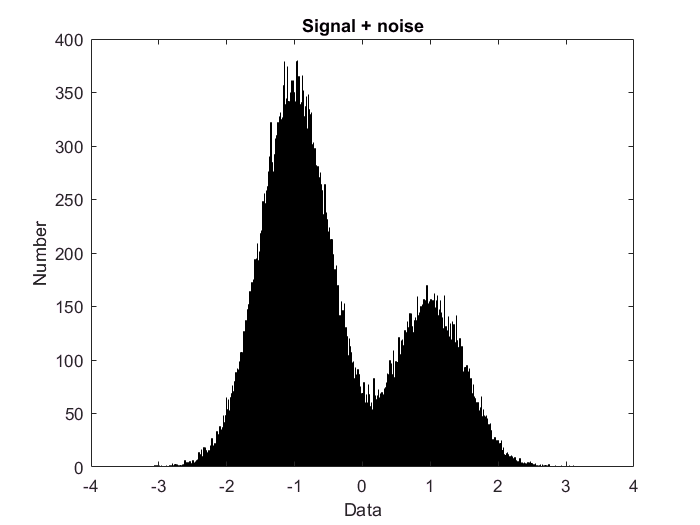

N = 99999;
n_bins=1000;
Z_array = zeros(1,N);
rng('shuffle');
Signal_4 = (2*randsrc(1, N, [0,1; 0.7,0.3]) - 1);
Noise_4 = normrnd(0, 0.5,size(Z_array));
R = Signal_4 + Noise_4;
histogram(R, n_bins)
xlabel ('Data');
ylabel ('Number');
title ('Signal + noise')

Part 5.

here for calculating the quantity of our error we have to send so many +1 & -1 and then with specific method clarify them as being +1 or -1 and then the ratio of correct clarification to the total number of data SNR is calculated.in this method the level of dicision is zero.

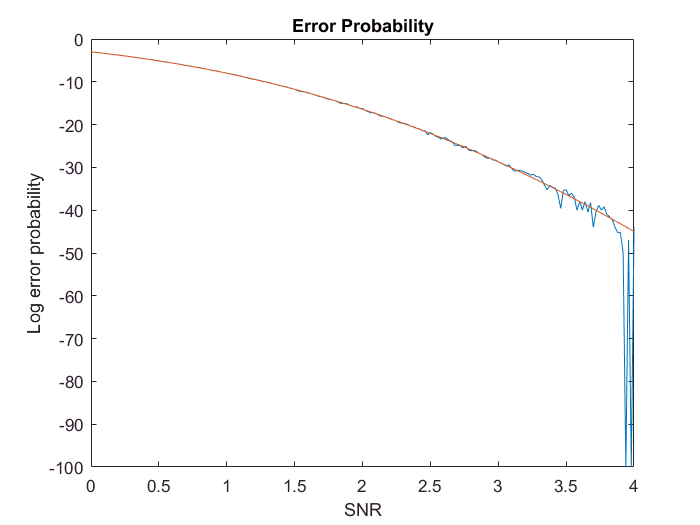

N = 99999;
n_bins=45;
Z_array = zeros(1,N);
rng('shuffle');
SNR = 0:0.02:4;
P = zeros(size(SNR));
i = 1;
for A = 0:0.02:4
    Signal_5 = (2*randi([0, 1], size(Z_array)) - 1);
    Noise_5 = normrnd(0, 1, [1 N]);
    R = (A * Signal_5) + Noise_5;
    %decision making
    R(R >= 0) = 1;
    R(R < 0) = -1;
    Correct =  find(R ~= Signal_5);
    P(i) = size(Correct)/size(Signal_5);
    i = i + 1;
end
plot(SNR, 10 * log10(P));
hold on
plot(SNR, 10 * log10(qfunc(SNR)));
xlabel ('SNR');
ylabel ('Log error probability');
title ('Error Probability');
hold off